%执行'ctsdm_ntf.mlx'脚本
ctsdm_ntf;

ntf =
 
         (z-1) (z^2 - 2z + 1)
  ----------------------------------
  (z-0.6694) (z^2 - 1.531z + 0.6639)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.


Hz =
 
  0.79963 (z^2 - 1.64z + 0.6949)
  ------------------------------
       (z-1) (z^2 - 2z + 1)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.


Hs =
 
  0.67032 (s^2 + 0.364s + 0.06564)
  --------------------------------
        s (s^2 + 0.0002132)
 
Continuous-time zero/pole/gain model.



Td = 0.4*Ts;%dac delay,0.8个时钟周期，Ts对时钟周期进行归一化

% %firc 

% 
% %1/s,1/s^2,1/s^3的脉冲响应
% x1 = impulse(c2d(tf([1],[1 0]),1),10)
% x2 = impulse(c2d(tf([1],[1 0 0]),1),10)
% x3 = impulse(c2d(tf([1],[1 0 0 0]),1),10)
% 
% %理想的 Hs=k1/s+k2+s^2+k3/s^3;
% imp_lct = x1*k1+x2*k2+x3*k3;
% 
% Fz = tf([1,1,1,1,1,1],[6,0,0,0,0,0],1)%fir滤波器的传输函数
% %先不考虑dac delay,只考虑fir延迟问题
% % x1d = impulse((c2d(tf([1],[1 0]),1)*Fz),10)
% x2d = impulse((c2d(tf([1],[1 0 0] ),1)*Fz),10)
% x3d = impulse((c2d(tf([1],[1 0 0 0]),1)*Fz),10)
% 
% M= 6;
% k3d = k3;
% k2d = k2+k3*(M-1)/2;
% k1d = k1+k2*(M-1)/2+k3*(M-1)*(M-2)/12;
% 
% imp_lct_delay = x2d*k2d+x3d*k3d;
% 
% %(k3d*x3+K2d*x2)*Fz + Fcz*x1 = k3*x3+k2*x2+k1*x1
% 
% delta = imp_lct - imp_lct_delay
% % Fcz的脉冲响应为delta
% 
% kc(1)=delta(2)
% kc(2)=delta(3)-delta(2)
% kc(3)=delta(4)-delta(3)
% kc(4)=delta(5)-delta(4)
% kc(5)=delta(6)-delta(5)
% kc(6)=delta(7)-delta(6)
% 
% Fcz = tf(kc,[1,0,0,0,0,0],1)
% 
% x1d_c = impulse((c2d(tf([1],[1 0]),1)*Fcz),10)
% % kc = delta(1:6,1)
% % kc = kc'
% % 
% % Fcz = tf(kc,[1,0,0,0,0,0],1)
% % 
% % xc = impulse(Fcz,10)
% % x1d = impulse((c2d(tf([1],[1 0]),1)*Fz),10)
% % x1d_c = impulse((c2d(tf([1],[1 0]),1)*Fcz),10)
% 
% 
% 
% imp_lct_comp = x2d*k2d+x3d*k3d + x1d_c;
% 
% 
% 
% plot_imp_reponse_delay = 1;
% 
% if plot_imp_reponse_delay == 1
% figure;
% plot(0:10,imp_lct,'o');
% hold on;
% plot(0:10,imp_lct_delay,'g');
% 
% hold on;
% 
% plot(0:10,imp_lct_comp,'r');
% legend('imp_lct','imp_lct_delay','imp_lct_comp');
% grid on;
% 
% end
% 
% %调整k1，k2,k3的值
% k2=k2d
% k3=k3d
% k1=k1d

%执行'ctsdm_ntf_scale.mlx'脚本
ctsdm_ntf_scale;

c1 = 0.2500

k2 = 0.9765

c2 = 0.4000

k3 = 0.4398

c3 = 0.2500

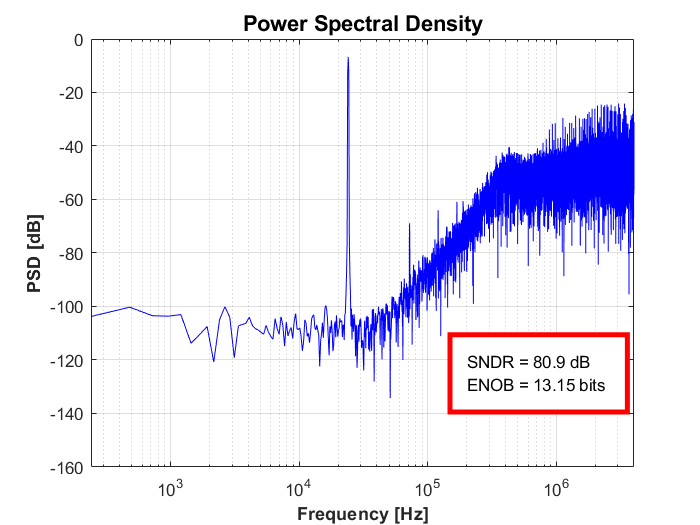


% %jitter
% Jitter=50e-12;
% Variance=1e-4*Ts;%[0.1%,1%]

sim('ctsdm_3stage_NRZ_DAC.slx');